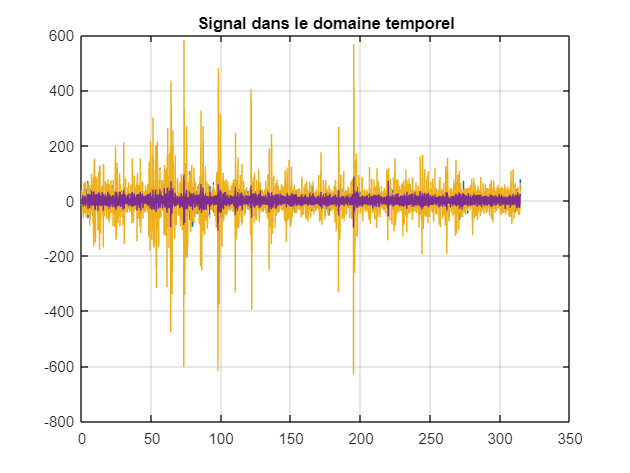

%% suppression de bruit, mouvements oculaires et signaux musculaires %%

eeg_data = csvread("data/Essai_1704_Test2.csv",1,0);
eeg_data1 = eeg_data(:,[1:8]); %toutes les électrodes
eeg_data2 = eeg_data(:,[1:4]); %électrodes 1,2,3,4

Fe = 250;
N = length(eeg_data2);
t = [0:N-1]/Fe;

figure(1)
plot(t,eeg_data2),grid
title('Signal dans le domaine temporel')

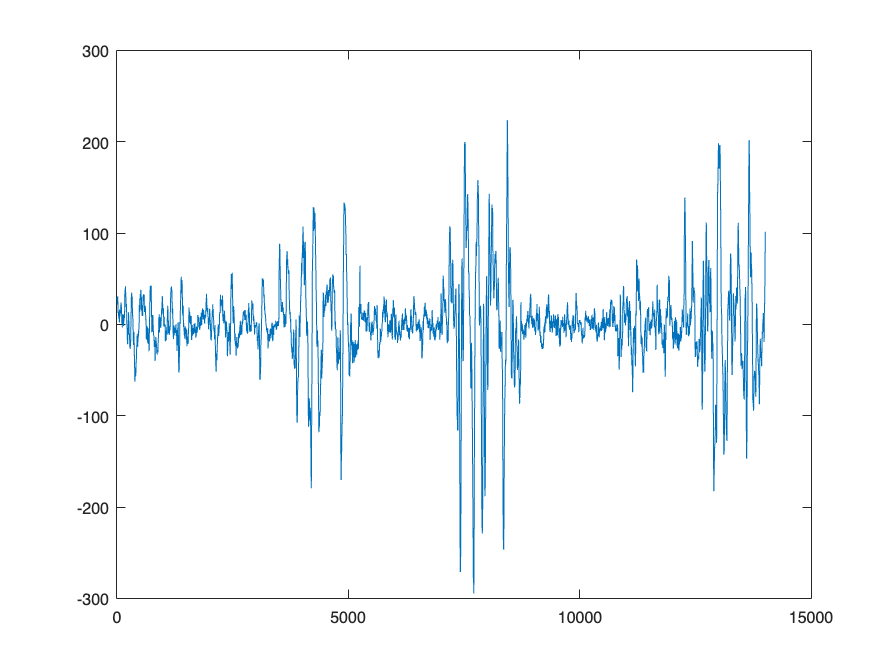

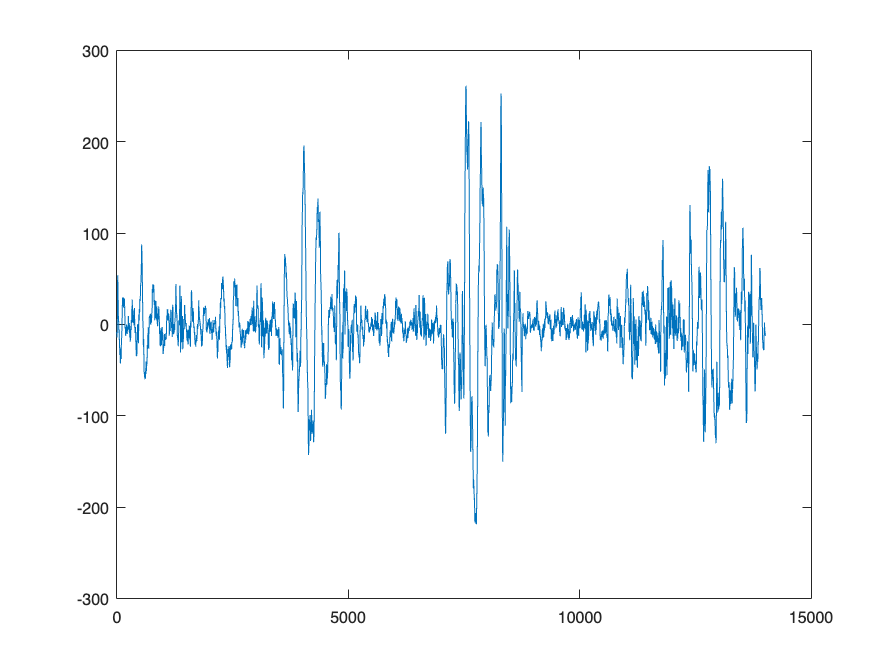

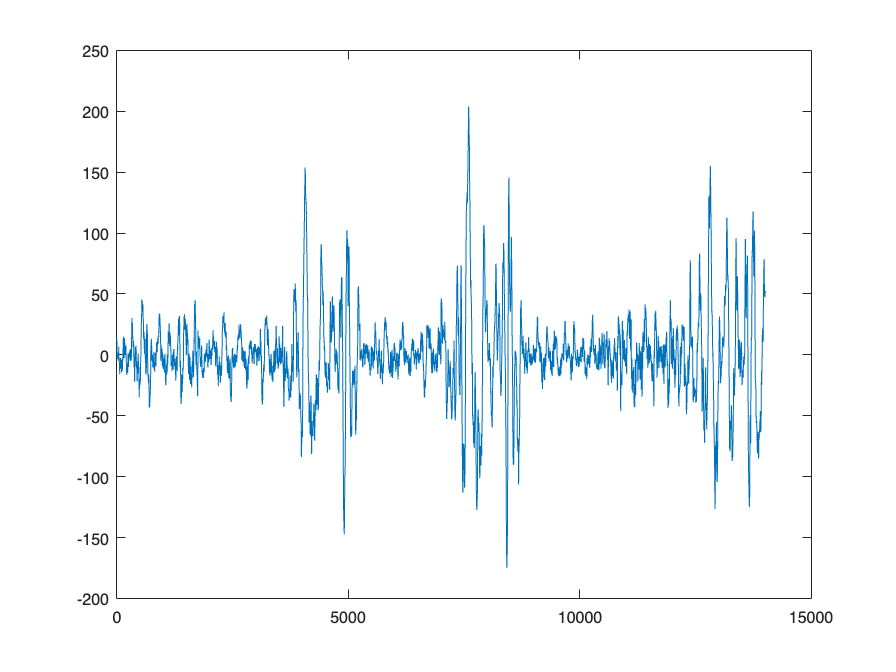

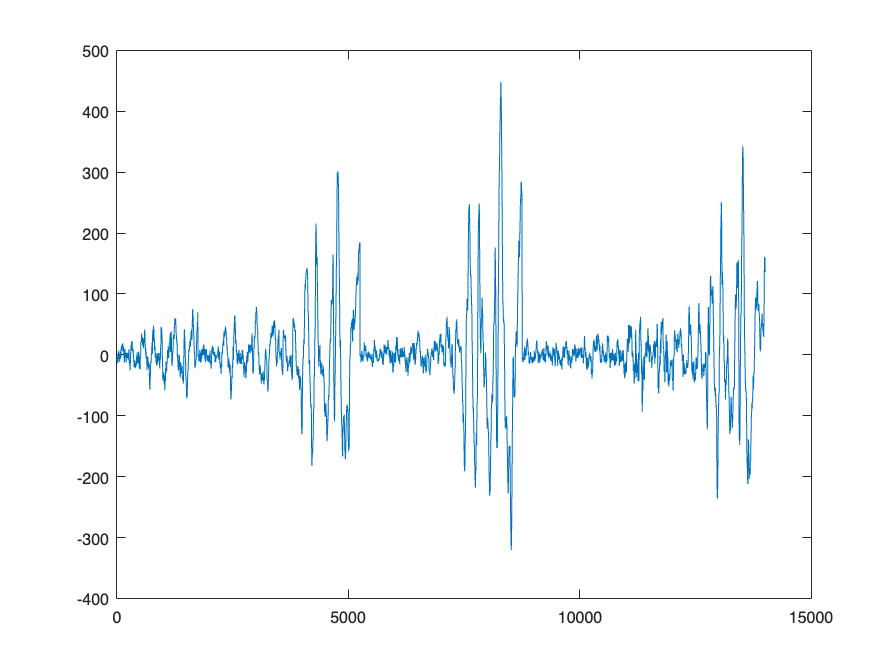

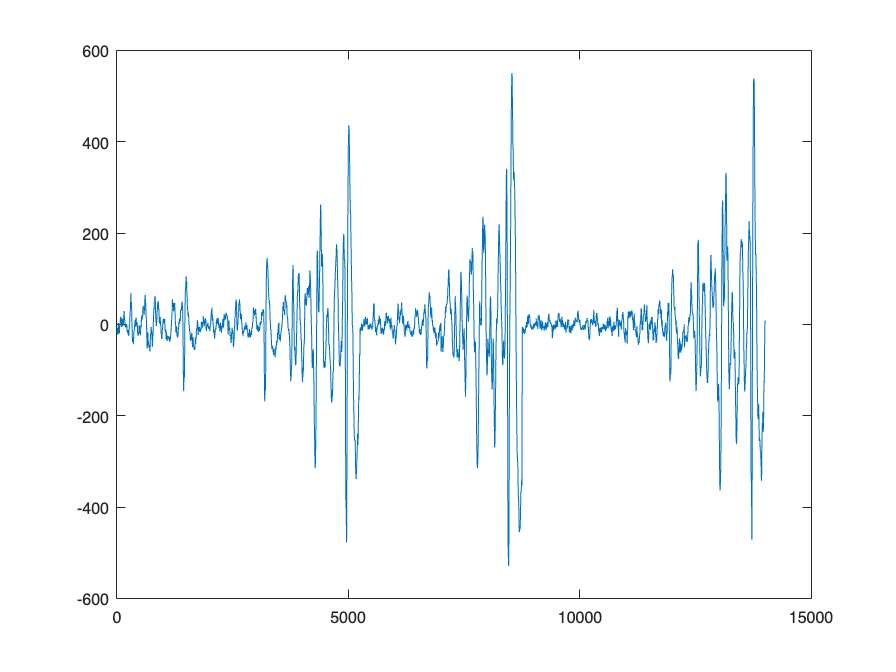

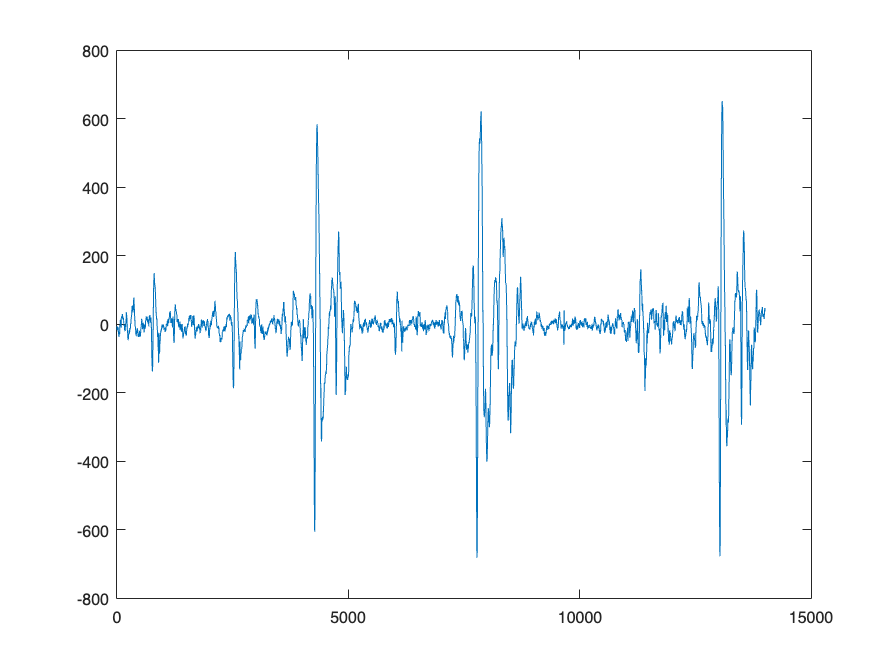

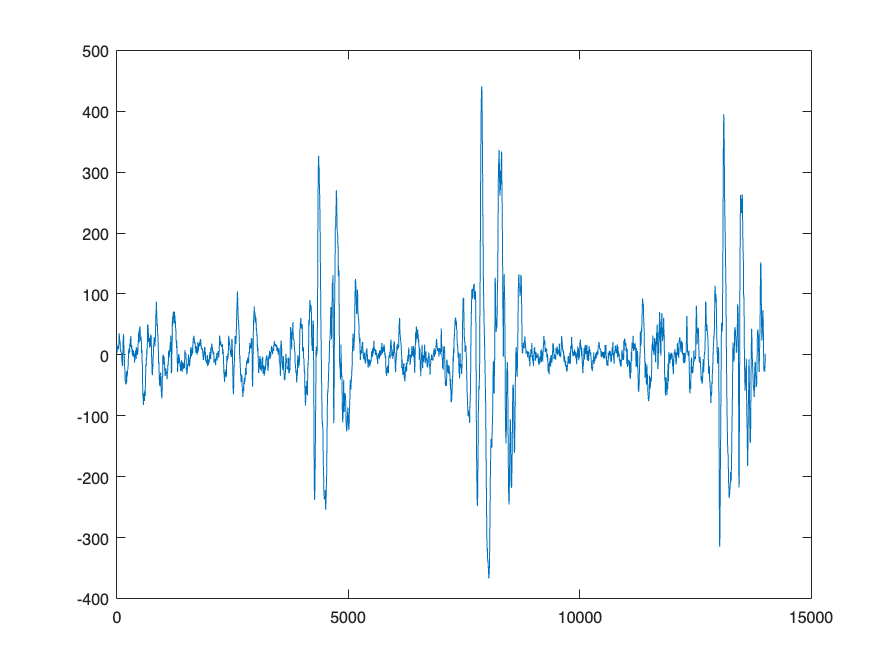

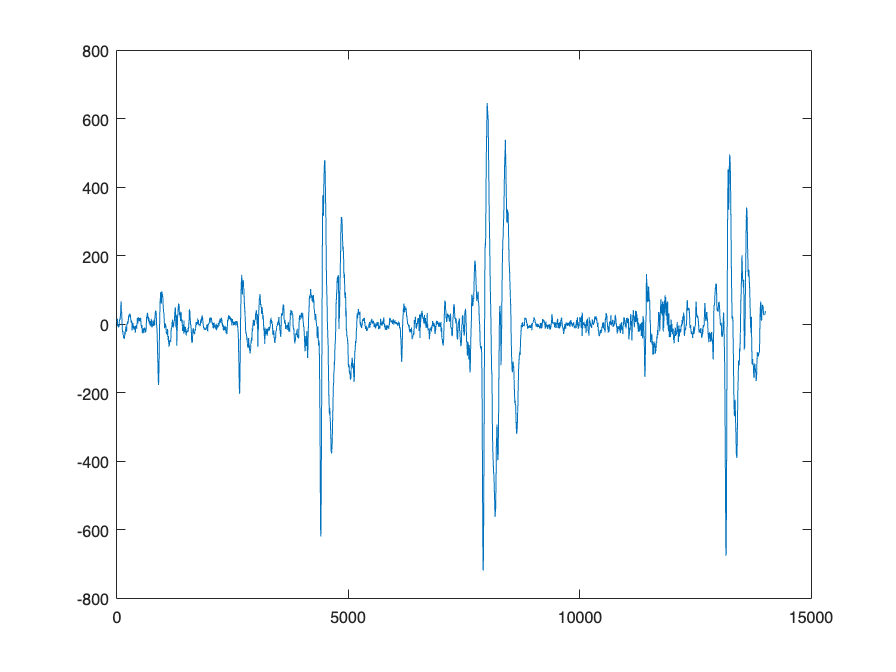

clear all
data = readmatrix("data/Essai_1704_Test2.csv");
data = data(:,1:8);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
signalDuration = size(data,1)/fs;
segmentDuration = 7;
totalSegments = 26;
% Objectif : prendre les signaux toutes les 5 secondes (5*250) pendant
% 7 secondes (7*250)
N = 75000;
decompte = 5*250;
nn = N/25;
ii = 0;
t = 1/(7*250);

for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) == 0
        label = 'Droite';
        mouvement = data(startIndexSignal:endIndexSignal, :);
        droite = [mouvement(:,1);...
            mouvement(:,2);...
            mouvement(:,3);...
            mouvement(:,4);...
            mouvement(:,5);...
            mouvement(:,6);...
            mouvement(:,7);...
            mouvement(:,8)];
        figure;
        
        plot(t,droite)
        title('Signal mouvement main droite');xlabel('Time (s)');ylabel('Amplitude');
    else
        label = 'Gauche';
        mouvement = data(startIndexSignal:endIndexSignal, :);
        gauche = [mouvement(:,1);...
            mouvement(:,2);...
            mouvement(:,3);...
            mouvement(:,4);...
            mouvement(:,5);...
            mouvement(:,6);...
            mouvement(:,7);...
            mouvement(:,8)];
        figure;
        plot(t,gauche)
        title('Signal mouvement main gauche');xlabel('Time (s)');ylabel('Amplitude');
    end
end